% Phaser Specifications
Pt_peak = 1*10^(-3);        % Peak transmit power (W)
G = 16;                     % Gain of the Antenna (dB)
G = 10^(G/10);              % Gain of the Antenna (ratio)
f = 10e9;                   % Transmit Frequency
c = physconst('LightSpeed');% Speed of Light
lambda = c/f;               % Transmit Wavelength


% RCS of 6 inch sphere
d = 6;                      % 6 Inch diameter metal sphere
d = d/39.37;                % Convert to meters
r = d/2;                    % Radius
RCS_6 = pi*r^2;             % RCS of target

% Calculating Receive Power Over Range
n = 100;
x = linspace(0,10,n);
Pr_6 = zeros(1,n);
for i = 1:n
    Pr_6(i) = (Pt_peak*G^2*lambda^2*RCS_6)/((4*pi)^3*x(i)^4);
    Pr_6(i) = 10*log10(Pr_6(i))+30;
end

R = 3;
Pr_6_3m = (Pt_peak*G^2*lambda^2*RCS_6)/((4*pi)^3*R^4)

Pr_6_3m = 1.6165e-10

Pr_6_3m = 10*log10(Pr_6_3m)+30

Pr_6_3m = -67.9141

% RCS of 12 inch sphere
d = 12;                     % 6 Inch diameter metal sphere
d = d/39.37;                % Convert to meters
r = d/2;                    % Radius
RCS_12 = pi*r^2;            % RCS of target

% Calculating Receive Power Over Range
Pr_12 = zeros(1,n);
for i = 1:n
    Pr_12(i) = (Pt_peak*G^2*lambda^2*RCS_12)/((4*pi)^3*x(i)^4);
    Pr_12(i) = 10*log10(Pr_12(i))+30;
end

Pr_12_3m = (Pt_peak*G^2*lambda^2*RCS_12)/((4*pi)^3*R^4)

Pr_12_3m = 6.4662e-10

Pr_12_3m = 10*log10(Pr_12_3m)+30

Pr_12_3m = -61.8935

% RCS of 7.75 Inch Corner Reflector
s = 7.75;                       % Corner Reflector Side of 7.75"
s = s/39.37;                    % Convert to meters
RCS_c = 4*pi*s^4/(3*lambda^2);  % RCS of target

% Calculating Receive Power Over Range
Pr_c = zeros(1,n);
for i = 1:n
    Pr_c(i) = (Pt_peak*G^2*lambda^2*RCS_c)/((4*pi)^3*x(i)^4);
    Pr_c(i) = 10*log10(Pr_c(i))+30;
end

Pr_c_3m = (Pt_peak*G^2*lambda^2*RCS_c)/((4*pi)^3*R^4)

Pr_c_3m = 6.2018e-08

Pr_c_3m = 10*log10(Pr_c_3m)+30

Pr_c_3m = -42.0748

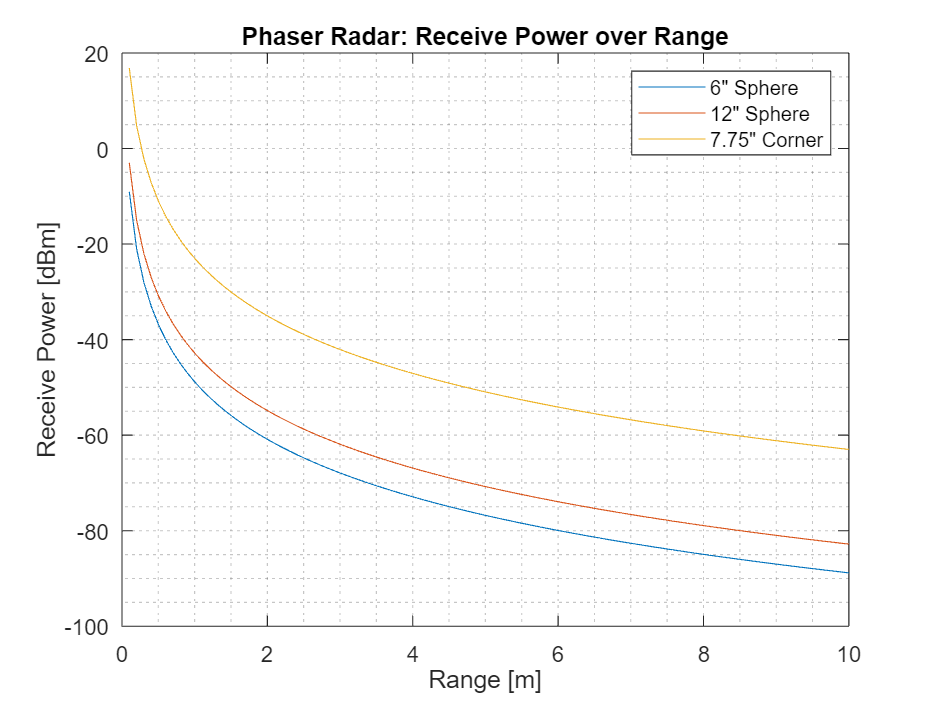

% Plotting
plot(x,Pr_6)
hold on
plot(x,Pr_12)
plot(x,Pr_c)
grid minor
title('Phaser Radar: Receive Power over Range')
xlabel('Range [m]')
ylabel('Receive Power [dBm]')
legend('6" Sphere','12" Sphere','7.75" Corner')
hold off